## step 50 [deg] simulations for nominal tracking


% simulate value with no antiwindup filter step 50 [deg] nominal

step_amplitude = 50;

data = sim("lab3_ss_nominal_sim.slx");

t = data.ScopeData1.time;
tetha_h = data.ScopeData1.signals(1).values;  
tetha_d = data.ScopeData1.signals(2).values;
ref_signal = data.ScopeData1.signals(3).values;
command_u =  data.ScopeData1.signals(4).values;

save("SS_data_lab3_50_nominal.mat",'t','tetha_h','tetha_d','ref_signal','command_u');



## Stampa grafico

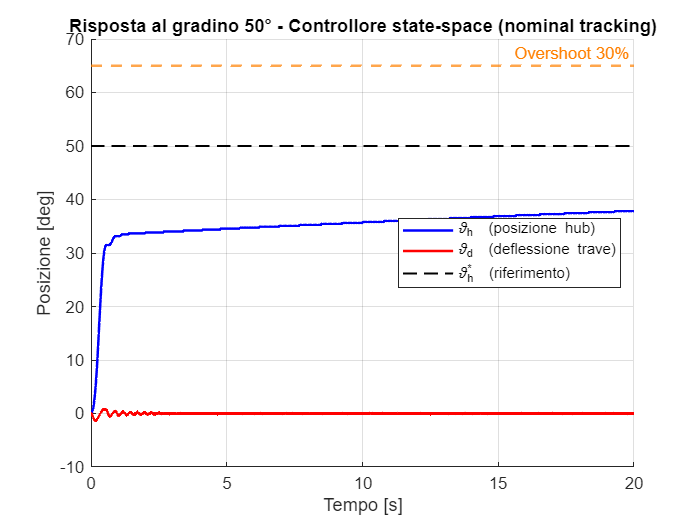

load("SS_data_lab3_50_nominal.mat");
% grafico step 50 deg

figure;
hold on
plot(t, tetha_h, 'b', 'LineWidth', 1.5);
plot(t, tetha_d, 'r', 'LineWidth', 1.5);
plot(t, ref_signal, 'k--', 'LineWidth', 1.2);
yline(65, '--', 'Color', [1, 0.5, 0], 'LineWidth', 1.5, ...
      'Label', 'Overshoot 30%', 'LabelHorizontalAlignment', 'right');
hold off
axis([0 20 -10 70])
grid on
xlabel('Tempo [s]')
ylabel('Posizione [deg]')
title('Risposta al gradino 50° - Controllore state-space (nominal tracking)')
legend('\vartheta_h  (posizione hub)', ...
       '\vartheta_d  (deflessione trave)', ...
       '\vartheta_h^*  (riferimento)', ...
       'Location', 'east')

#### Step response parameters


step_50_wind_up = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up);

         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: 0
       Undershoot: 0
             Peak: 38.7000
         PeakTime: 24.0690

